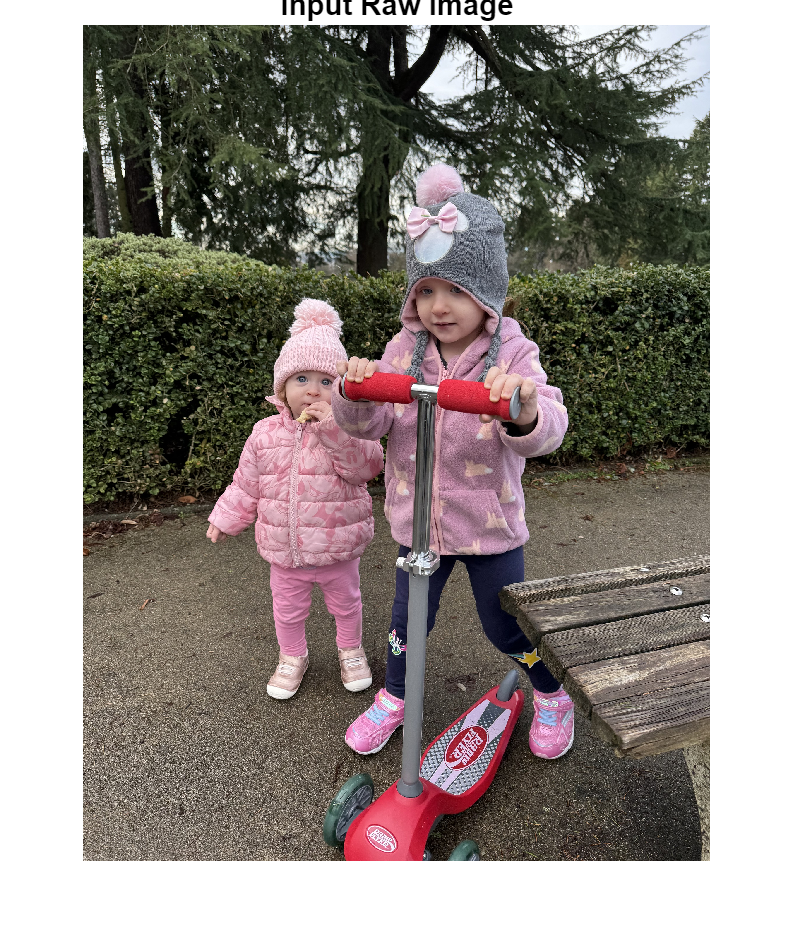

%% MATLAB Assignment 1
% This code performs the following functions: reads an image, displays it, applies a filter, and saves the result.

%% Table of Contents:
% A. Reads an image into a workspace variable and displays the image.
% B. Applies an image processing filter to the image.
% C. Displays the result and saves the resulting image to a .png file.

% A. Reads and Displays Image
img = imread('IMG_3357.jpg');
imshow(img);
title('Input Raw Image');

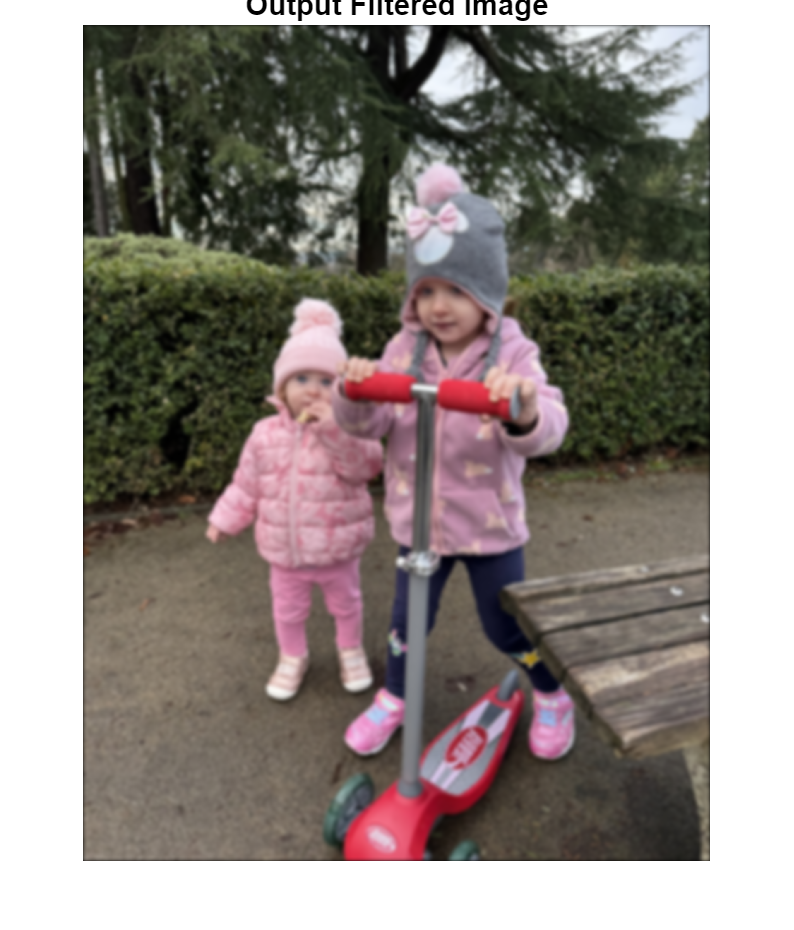


% B. Apply Gaussian Blur Filter
h = fspecial('gaussian', [29 29], 7);
img_filtered = imfilter(img, h);
figure;
imshow(img_filtered);
title('Output Filtered Image');


% C. Display and Save Result as a .png file.
imwrite(img_filtered, 'filtered_image.png');